# Test PenguinPi web API

url = "http://131.181.33.163:8080";

## Test ADC

webread(url+"/battery/get/voltage")

ans = '11937.9892578125'

webread(url+"/battery/get/current")

ans = '304.57708740234375'

## Test LEDs

for i=2:4
    webread(url+"/led/set/state", "id", i, "value", 1);
    pause(0.5)
    webread(url+"/led/set/state", "id", i, "value", 0);
end

for i=2:4
    webread(url+"/led/set/count", "id", i, "value", 100);
    pause(0.5)
end


## Test HAT

webread(url+"/hat/dip/get")

ans = '240'

webread(url+"/hat/button/get")

ans = '0'

for i=0:15
    webread(url+"/hat/ledarray/set", "value", 2^i);
end
webread(url+"/hat/ledarray/set", "value", 0);

for i=0:6
    webread(url+"/hat/screen/set", "value", i);
    pause(1)
end
webread(url+"/hat/screen/set", "value", 0);

## Motor

for i=0:1
    webread(url+"/motor/get/encoder", "id", i)
    webread(url+"/motor/get/kvp", "id", i)
    webread(url+"/motor/get/kvi", "id", i)
end

ans = '0'

ans = '0'

ans = '1'

ans = '0'

ans = '0'

ans = '1'

for i=0:1webread(url+"/motor/set/velocity", "id", i, "value", 20)
    pause(0.5)
    webread(url+"/motor/set/velocity", "id", i, "value", 0);
end


ans =

  1×0 empty char array


ans =

  1×0 empty char array



## Robot

### Test move

json1 = webread(url+"/robot/set/velocity", "value", [20 -20]);
pause(2)
json2 = webread(url+"/robot/stop");
print_json(json1, json2)

Initial


ans = struct with fields:
     left: 108
    right: 92


ans = struct with fields:
        x: -0.3589
        y: 0.4880
    theta: -1.8735


Final


ans = struct with fields:
     left: 494
    right: -257


ans = struct with fields:
        x: -0.3625
        y: 0.4761
    theta: 0.5672


pause(2)


### Test move with time

json1 = webread(url+"/robot/set/velocity", "value", [20 -20], "time", 2);
pause(2)
json2 = webread(url+"/robot/stop");
print_json(json1, json2)

Initial


ans = struct with fields:
     left: 907
    right: -669


ans = struct with fields:
        x: -0.3619
        y: 0.4763
    theta: 3.2602


Final


ans = struct with fields:
     left: 928
    right: -696


ans = struct with fields:
        x: -0.3607
        y: 0.4769
    theta: 3.5772


pause(2)

### Test move with time and acceleration

json1 = webread(url+"/robot/set/velocity", "value", [20 -20], "time", 4, "acceleration", 1);
pause(2)
json2 = webread(url+"/robot/stop")

json2 = '{"encoder": {"left": 1748, "right": -1517}, "pose": {"x": -0.35998471127378984, "y": 0.4759983620807791, "theta": 2.8879744966593686}}'


print_json(json1, json2)

Initial


ans = struct with fields:
     left: 1728
    right: -1490


ans = struct with fields:
        x: -0.3618
        y: 0.4766
    theta: 2.5028


Final


ans = struct with fields:
     left: 1748
    right: -1517


ans = struct with fields:
        x: -0.3600
        y: 0.4760
    theta: 2.8880


## Camera

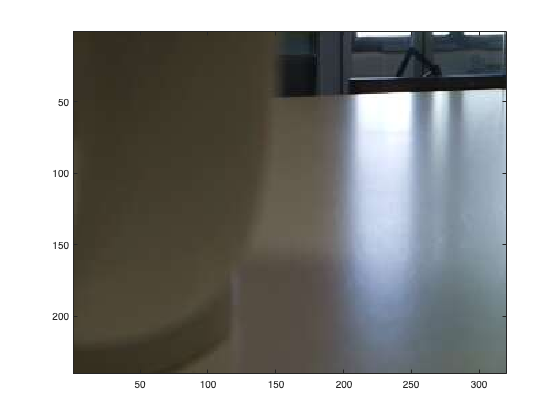

camera = ipcam(url + "/camera/get");
img = snapshot(camera);
image(img);

function print_json(j1, j2)
    state1 = jsondecode(j1);
    state2 = jsondecode(j2);
    fprintf('Initial\n');
    state1.encoder
    state1.pose
    fprintf('Final\n');
    state2.encoder
    state2.pose
end